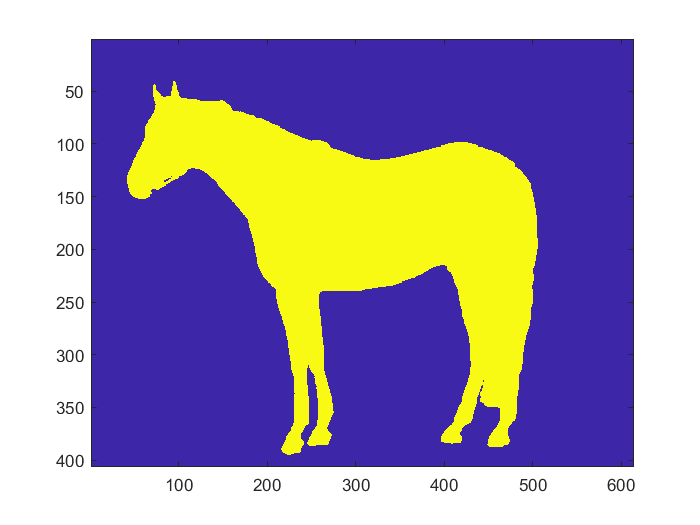

coord = csvread('data1.csv');  % input is coordinates of horse, as a table
coord(1,:) = [];
coord(:,1) = [];
rsn = 10;               % resolution of points of interest (POI)

image = imread("horse.png");

[s1,s2,s3] = size(image);
coord(:,2) = coord(:,2)*-1;

Area = zeros([s1,s2]);
pl = Area;


for i = 1:length(coord)
    Area(coord(i,2),coord(i,1)) = 1;
end

imagesc(Area)

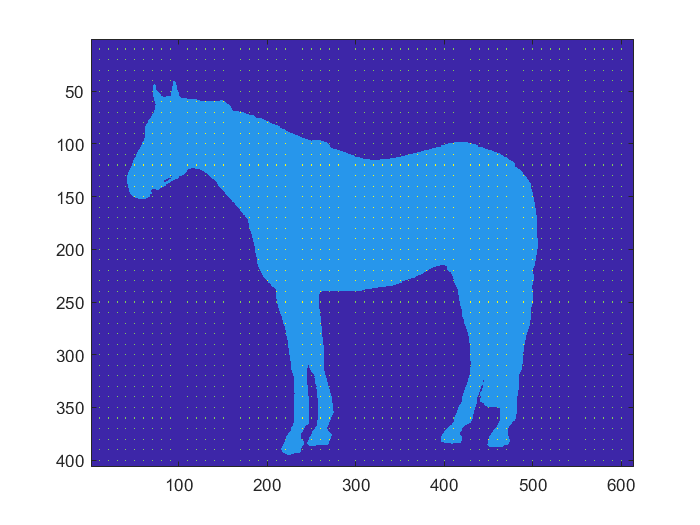


POI = Area;

for i = rsn:rsn:s1
    for j = rsn:rsn:s2
        if Area(i,j) == 0
           POI(i,j) = 2;
        else
            POI(i,j) = 3;
        end
        
    end
end

[c1,c2] = find(POI == 3);
COI = [c1,c2];                    % coordinates of all POI inside horse


imagesc(POI)   